# Train DDPG Agent to Swing Up and Balance Cart-Pole System

This example shows how to train a deep deterministic policy gradient (DDPG) agent to swing up and balance a cart-pole system modeled in Simscape™ Multibody™.

For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). For an example showing how to train a DDPG agent in MATLAB®, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

The example code may involve computation of random numbers at various stages such as initialization of the agent, creation of the actor and critic, resetting the environment during simulations, generating observations (for stochastic environments), generating exploration actions, and sampling min-batches of experiences for learning. Fixing the random number stream preserves the sequence of the random numbers every time you run the code and improves reproducibility of results. You will fix the random number stream at various locations in the example.

Fix the random number stream with the seed `0` and random number algorithm Mersenne Twister. For more information on random number generation see [`rng`](docid:matlab_ref#bsuymc2-1).

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


The output `previousRngState` is a structure that contains information about the previous state of the stream. You will restore the state at the end of the example. 

## Cart-Pole Simscape Model

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pole stand upright without falling over using minimal control effort.

Open the model.

mdl = "rlCartPoleSimscapeModel";
open_system(mdl)

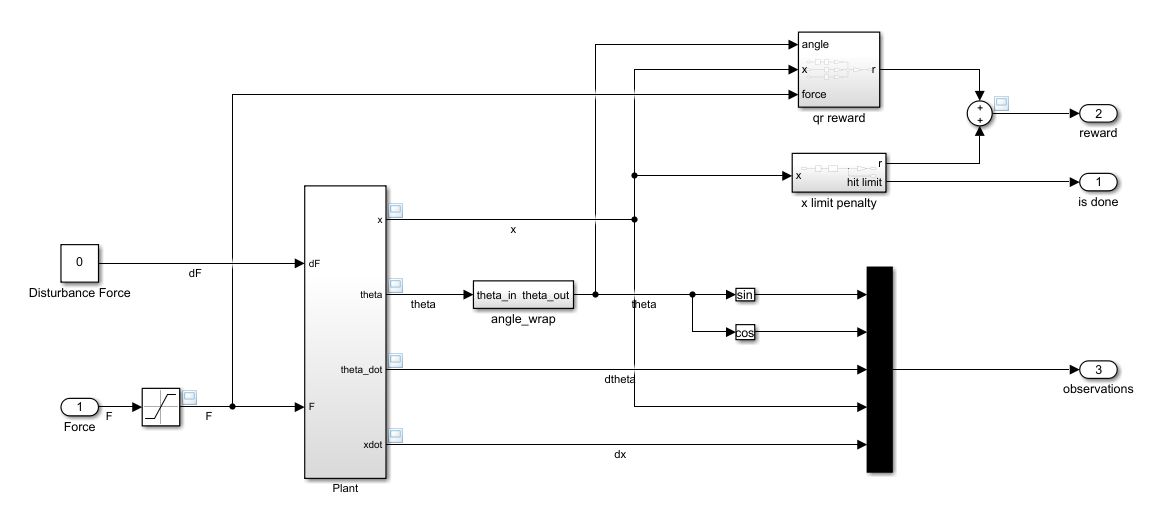

The cart-pole system is modeled using Simscape Multibody.

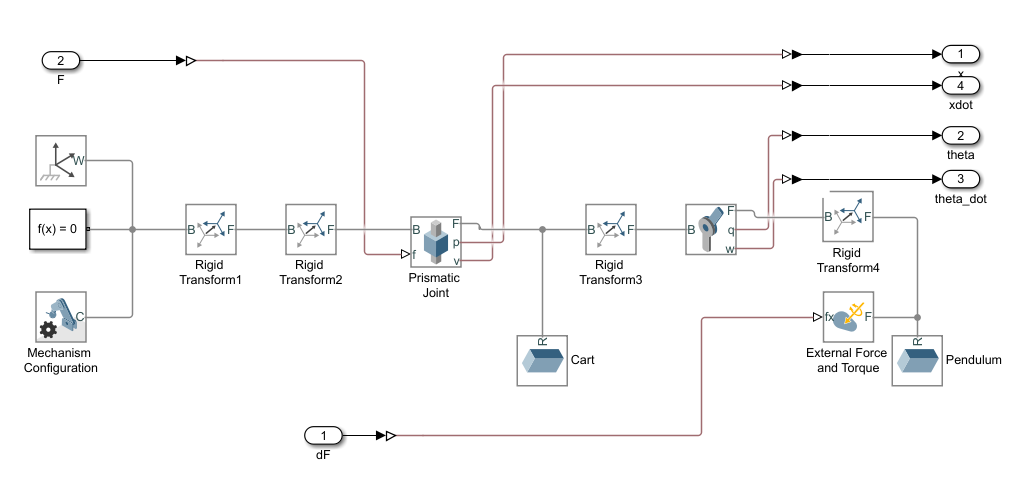

For this model:

- The upward balanced pole position is 0 radians, and the downward hanging position is `pi` radians.

- The force action signal from the agent to the environment is from –15 to 15 N.

- The observations from the environment are the position and velocity of the cart, and the sine, cosine, and derivative of the pole angle.

- The episode terminates if the cart moves more than 3.5 m from the original position.

- The reward $r_t$, provided at every timestep, is


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =\;-0\ldotp 1\left(5{\theta_{\mathit{\mathbf{t}}} }^2 \;+{x_{\mathit{\mathbf{t}}} }^2 \;+\;0\ldotp 05u_{t-1}^2 \right)-100B$$


Here:

- $\theta_t$ is the angle of displacement from the upright position of the pole.

- $x_t$ is the position displacement from the center position of the cart.

- $u_{t-1}$ is the control effort from the previous time step.

- $B$ is a flag (1 or 0) that indicates whether the cart is out of bounds.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Object

Create a predefined environment interface for the pole.

env = rlPredefinedEnv("CartPoleSimscapeModel-Continuous")

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlCartPoleSimscapeModel
      AgentBlock : rlCartPoleSimscapeModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The interface has a continuous action space where the agent can apply possible torque values from –15 to 15 N to the pole.

Obtain the observation and action information from the environment interface. 

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.02;
Tf = 25;

## Create DDPG Agent

You will create and train a DDPG agent in this example. The agent uses:

- A Q-value function critic to estimate the value of the policy. The critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward given the action from the state corresponding to the current observation, and following the policy thereafter).

- A deterministic policy over a continuous action space, which is learned by a continuous deterministic actor. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation.

The actor and critic functions are approximated using neural network representations. Create an agent initialization object to initialize the networks with the hidden layer size 200.

initOpts = rlAgentInitializationOptions(NumHiddenUnit=200);

Configure the hyperparameters for training using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

- Specify the actor and critic learning rates as 5e-3. A large learning rate causes drastic updates which may lead to divergent behaviors, while a low value may require many updates before reaching the optimal point.

- Specify a gradient threshold value of 1. Clipping the gradient improves learning stability.

- Specify the experience buffer capcity to be 1e5. A large capacity enables storing a diverse set of experiences.

- Specify a smoothing factor of 5e-3 to update the target critic network.

- Specify the sample time of the agent as `Ts`.

- Learn with a maximum of 200 mini batches per training epoch.

criticOptions = rlOptimizerOptions( ...
    LearnRate=5e-03, ...
    GradientThreshold=1);
actorOptions = rlOptimizerOptions( ...
    LearnRate=5e-03, ...
    GradientThreshold=1);
agentOptions = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceBufferLength=1e5,...
    TargetSmoothFactor=5e-3,...
    MaxMiniBatchPerEpoch=200);

Alternatively, you can also create the agent first, and then access its option object and modify the options using dot notation.

The DDPG agent in this example uses an Ornstein-Uhlenbeck (OU) noise model for exploration. Specify the following noise options using dot notation:

- Specify a mean attraction value of $0\ldotp 1/T_s$. A larger mean attraction value keeps the noise values close to the mean.

- Specify a standard deviation value of $1/\sqrt{T_s }$ to improve exploration during training.

agentOptions.NoiseOptions.StandardDeviation = 1.0/sqrt(Ts);
agentOptions.NoiseOptions.MeanAttractionConstant = 0.1/Ts;

Fix the random stream for reproducibility.

rng(0,"twister");

Then, create the agent using the input specification and agent options objects. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(obsInfo,actInfo,initOpts,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run each training episode for at most 2000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Reinforcement Learning Training Monitor dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Evaluate the performance of the greedy policy by running 1 simulation every 10 training episodes.

- Stop training when the greedy policy evaluation exceeds –390. At this point, the agent can quickly balance the pole in the upright position using minimal control effort.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0) and [`rlEvaluator`](docid:rl_ref#mw_4eee07a3-0481-43f5-b2d2-887af2f09847).

% training options
maxepisodes = 2000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=5,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=-390);

% agent evaluation
evl = rlEvaluator(NumEpisodes=1,EvaluationFrequency=10);

Fix the random stream for reproducibility.

rng(0,"twister");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions,Evaluator=evl);
else
    % Load the pretrained agent for the example.
    load("SimscapeCartPoleDDPG.mat","agent")
end

A snapshot of training progress is shown in the figure below. You can expect different results due to randomness in the training process.

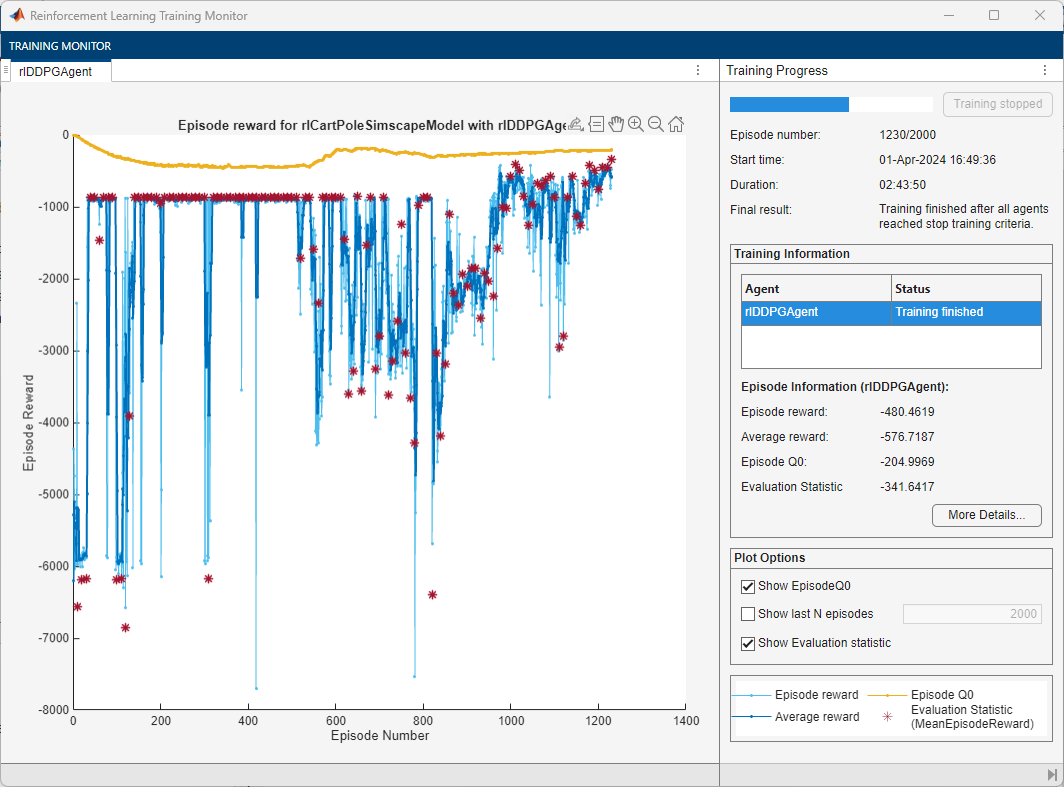

## Simulate DDPG Agent

Fix the random stream for reproducibility.

rng(0,"twister");

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=500);
experience = sim(env,agent,simOptions);

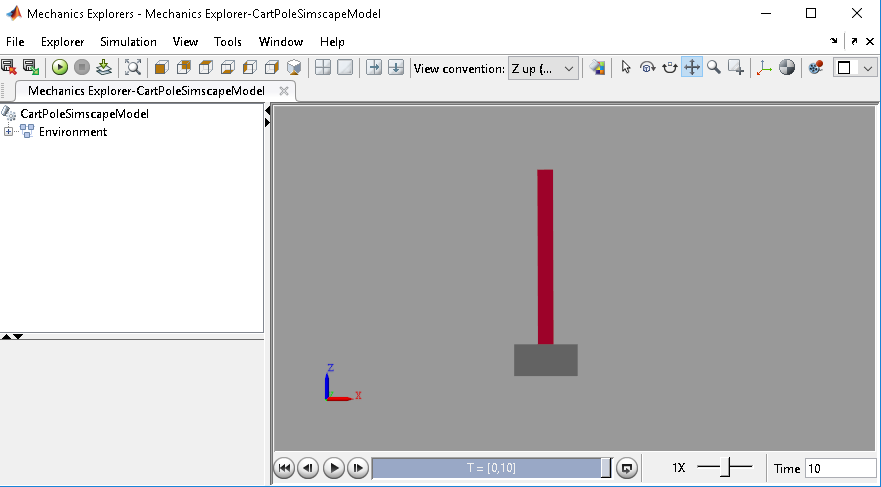

Restore the random number stream using the information stored in `previousRngState`.

rng(previousRngState);

*Copyright 2019-2024 The MathWorks, Inc.*